# Homework 1

## Problem 9.1

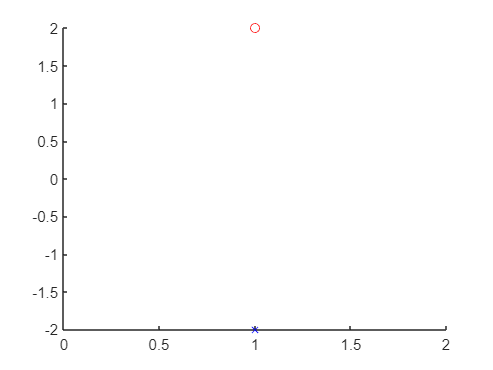

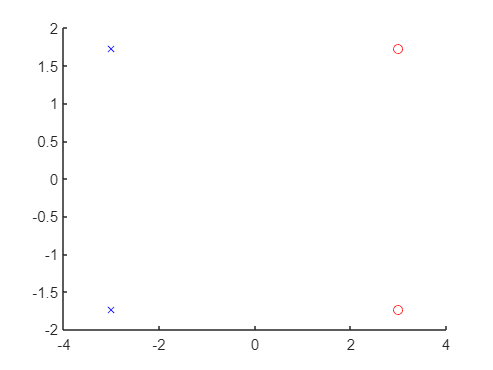

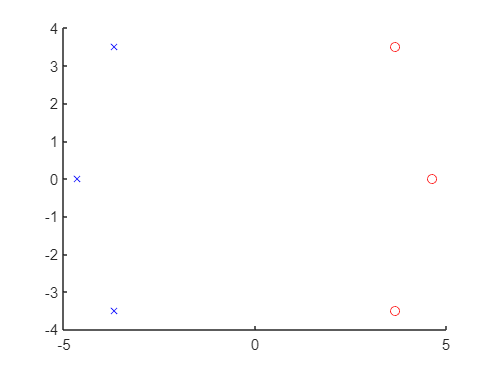

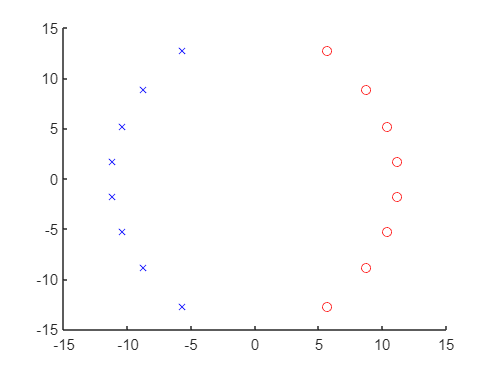

n = [1 2 3 8];

for i = 1:4
    k = pade(exp(-1*s),n(i));
    [o,x] = tfdata(k,'v');
    figure(i)
    hold on
    plot(roots(o),'ro')
    plot(roots(x),'bx')
    hold off
end

## Problem 9.12

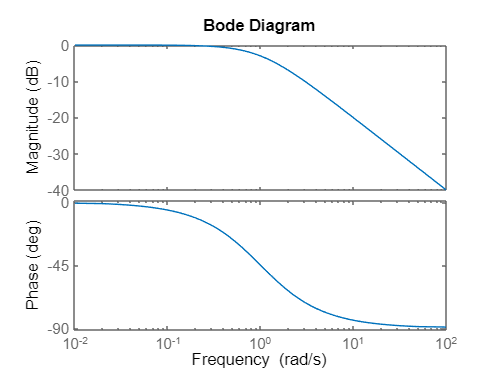

bode(tf([1],[1 1]))

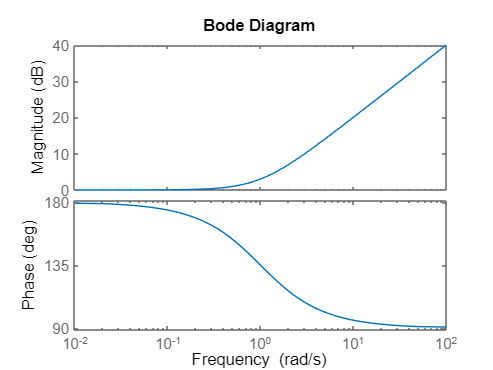

bode(tf([1 -1],[1]))

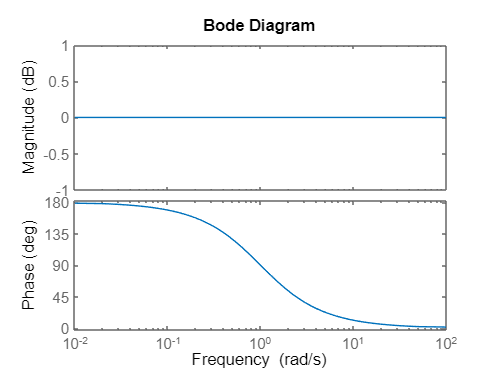

bode(tf([1 -1],[1 1]))

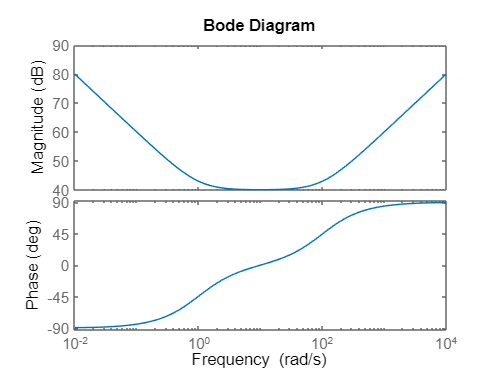

bode(tf([1 101 100],[1 0]))

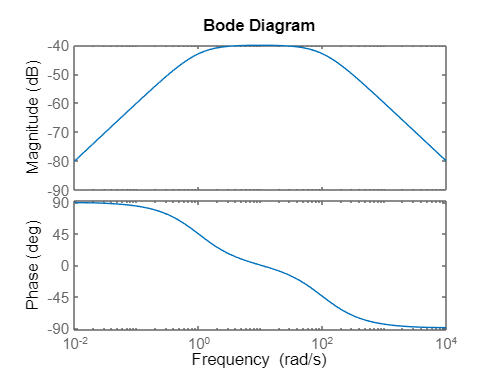

bode(tf([1 0],[1 101 100]))

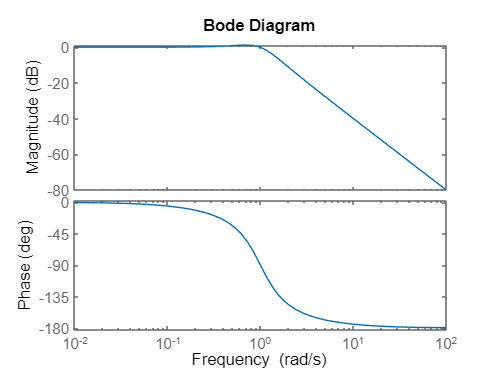

bode(tf([1],[1 1 1]))

## Problem 10.2

clear
syms L2 L5 s V0 
R1 =1e3; 
R4 =1e3; 
R3 =1e5;
A= [1 -1 -1 0 0 0 0 0 ; 0 1 0 -1 -1 0 0 0 ; 0 0 1 1 0 -1 0 0 ;
    0 R1 0 0 0 0 1 0 ; s*L2 0 -s*L2 0 0 0 0 1 ; 0 0 0 R3 0 0 -1 1 ;
    0 0 0 0 R4 0 -1 0 ; 0 0 0 0 0 -s*L5 0 1 ] 

$$A = \left(\begin{array}{cccccccc} 1 & -1 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & -1 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 1 & 0 & -1 & 0 & 0\\ 0 & 1000 & 0 & 0 & 0 & 0 & 1 & 0\\ L_{2}\,s & 0 & -L_{2}\,s & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 100000 & 0 & 0 & -1 & 1\\ 0 & 0 & 0 & 0 & 1000 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & -L_{5}\,s & 0 & 1 \end{array}\right)$$

b = [ 0 ; 0 ; 0 ; V0 ; 0 ; 0 ; 0 ; 0 ] 

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ V_{0}\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

x =A\b

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{V_{0}\,\left(101000\,L_{2}-100000\,L_{5}+L_{2}\,L_{5}\,s\right)}{\sigma_{1}}\\ -\frac{101\,V_{0}}{L_{2}\,s-201000}\\ \frac{V_{0}\,\left(101000\,L_{2}+1000\,L_{5}+L_{2}\,L_{5}\,s\right)}{\sigma_{1}}\\ -\frac{V_{0}\,\left(L_{2}\,s+1000\right)}{\sigma_{3}}\\ \frac{\sigma_{2}}{\sigma_{3}}\\ \frac{101\,L_{2}\,V_{0}}{L_{5}\,\left(L_{2}\,s-201000\right)}\\ \frac{\sigma_{2}}{L_{2}\,s-201000}\\ \frac{101\,L_{2}\,V_{0}\,s}{L_{2}\,s-201000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,L_{5}\,\left(L_{2}\,s-201000\right)\\ \sigma_{2}=V_{0}\,\left(L_{2}\,s-100000\right)\\ \sigma_{3}=1000\,\left(L_{2}\,s-201000\right) \end{array}$$

## Problem 10.5

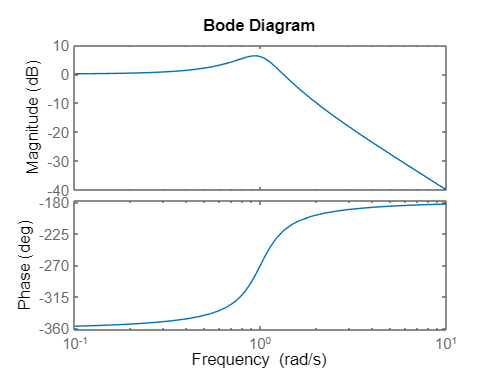

bode(tf([1],[1 -0.5 1]))